% Load IEEE 9-bus system data
run('ieee9_A2.m');


%% Q1

% Number of buses - from the previous assignment
Y = admittance(nfrom, nto, r, x, b);

[V_nrpf, delta_nrpf, Psl_nrpf, Qgv_nrpf, N_nrpf, time_nrpf] = nrpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter);

% Display the results
fprintf('Q1: \n');

Q1: 


fprintf('Converged in %d iterations and took %f seconds.\n', N_nrpf, time_nrpf);

Converged in 4 iterations and took 0.000409 seconds.


disp('Voltage magnitudes (p.u.):');

Voltage magnitudes (p.u.):


disp(V_nrpf);

    1.0000
    1.0000
    1.0000
    0.9870
    0.9755
    1.0034
    0.9856
    0.9962
    0.9576



disp('Voltage angles (radians):');

Voltage angles (radians):


disp(delta_nrpf);

         0
    0.1688
    0.0833
   -0.0420
   -0.0701
    0.0336
    0.0108
    0.0663
   -0.0759



disp('Active power at slack bus (MW):');

Active power at slack bus (MW):


disp(Psl_nrpf);

   71.9547



disp('Reactive power at PV buses (Mvar):');

Reactive power at PV buses (Mvar):


disp(Qgv_nrpf);

         0
   14.4601
   -3.6490
         0
         0
         0
         0
         0
         0





%% Q2

fprintf('Q2: \n');

Q2: 


[V_decpf, delta_decpf, Psl_decpf, Qgv_decpf, N_decpf, time_decpf] = decpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter);

% Display the results
fprintf('Converged in %d iterations and took %f seconds.\n', N_decpf, time_decpf);

Converged in 5 iterations and took 0.000404 seconds.


disp('Voltage magnitudes (p.u.):');

Voltage magnitudes (p.u.):


disp(V_decpf);

    1.0000
    1.0000
    1.0000
    0.9870
    0.9755
    1.0034
    0.9857
    0.9962
    0.9576



disp('Voltage angles (radians):');

Voltage angles (radians):


disp(delta_decpf);

         0
    0.1687
    0.0833
   -0.0420
   -0.0701
    0.0336
    0.0108
    0.0663
   -0.0759



disp('Active power at slack bus (MW):');

Active power at slack bus (MW):


disp(Psl_decpf);

   71.9545



disp('Reactive power at PV buses (Mvar):');

Reactive power at PV buses (Mvar):


disp(Qgv_decpf);

         0
   14.4533
   -3.6550
         0
         0
         0
         0
         0
         0





%% Q3

fprintf('Q3: \n');

Q3: 


[V_fastdecpf, delta_fastdecpf, Psl_fastdecpf, Qgv_fastdecpf, N_fastdecpf, time_fastdecpf] = fastdecpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter);

% Display the results
fprintf('Converged in %d iterations and took %f seconds.\n', N_fastdecpf, time_fastdecpf);

Converged in 5 iterations and took 0.000550 seconds.


disp('Voltage magnitudes (p.u.):');

Voltage magnitudes (p.u.):


disp(V_fastdecpf);

    1.0000
    1.0000
    1.0000
    0.9870
    0.9755
    1.0034
    0.9857
    0.9962
    0.9577



disp('Voltage angles (radians):');

Voltage angles (radians):


disp(delta_fastdecpf);

         0
    0.1687
    0.0833
   -0.0420
   -0.0701
    0.0336
    0.0108
    0.0663
   -0.0759



disp('Active power at slack bus (MW):');

Active power at slack bus (MW):


disp(Psl_fastdecpf);

   71.9518



disp('Reactive power at PV buses (Mvar):');

Reactive power at PV buses (Mvar):


disp(Qgv_fastdecpf);

         0
   14.4363
   -3.6614
         0
         0
         0
         0
         0
         0





%% Q4


fprintf('Q4: \n');

Q4: 


[delta_dcpf, Psl_dcpf, Pf_dcpf] = dcpf(nfrom, nto, x, is, Pg, Pd, Sbase);

% Display the results
disp('Voltage angles (radians):');

Voltage angles (radians):


disp(delta_dcpf);

         0
    0.1710
    0.0883
   -0.0386
   -0.0652
    0.0385
    0.0144
    0.0691
   -0.0709



disp('Active power at slack bus (MW):');

Active power at slack bus (MW):


disp(Psl_dcpf);

    67



disp('Active power at transmission line (MW):');

Active power at transmission line (MW):


disp(Pf_dcpf);

   67.0000
   28.9674
  -61.0326
   85.0000
   23.9674
  -76.0326
 -163.0000
   86.9674
  -38.0326






%% Q5 Compare AC vs DC active line flows

Sij_complex = compute_acpf(V_fastdecpf, delta_fastdecpf, Y, nfrom, nto, Sbase);

fprintf('Q5: Compare AC vs DC active line flows\n');

Q5: Compare AC vs DC active line flows


fprintf('\nLine  from-to    P_AC(MW)     S_AC(MVA)      P_DC(MW)     |P_AC|(MW)    |S_AC|(MVA)\n');


Line  from-to    P_AC(MW)     S_AC(MVA)      P_DC(MW)     |P_AC|(MW)    |S_AC|(MVA)


for e = 1:numel(nfrom)
    Pf_ac = real(Sij_complex(e));
    Sf_ac = abs(Sij_complex(e));
    Pf_diff = Pf_ac - Pf_dcpf(e);
    Sf_diff = Sf_ac - abs(Pf_dcpf(e));
    
    fprintf('%2d    %d  -> %d   %9.3f     %9.3f     %9.3f     %9.3f     %9.3f\n', e, nfrom(e), nto(e), Pf_ac, Sf_ac, Pf_dcpf(e), abs(Pf_ac), abs(Sf_ac));
end

 1    1  -> 4      71.952        75.862        67.000        71.952        75.862
 2    4  -> 5      30.680        31.493        28.967        30.680        31.493
 3    5  -> 6     -59.419        59.423       -61.033        59.419        59.423
 4    3  -> 6      84.999        85.077        85.000        84.999        85.077
 5    6  -> 7      24.112        28.420        23.967        24.112        28.420
 6    7  -> 8     -75.977        76.051       -76.033        75.977        76.051
 7    8  -> 2    -162.990       163.006      -163.000       162.990       163.006
 8    8  -> 9      86.497        87.415        86.967        86.497        87.415
 9    9  -> 4     -40.962        49.408       -38.033        40.962        49.408




%% Q6 Feasibility (at bus 7)

run('ieee9_A2.m');

fprintf('Q6: Feasibility (at bus 7)\n');

Q6: Feasibility (at bus 7)



P7_vals = 0:20:400; Q7_vals = -200:20:200;
feas = pf_feasibility_map(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, P7_vals, Q7_vals, toler, maxiter);
fprintf('\nFeasibility map computed on %dx%d grid. Feasible points: %d\n', numel(P7_vals), numel(Q7_vals), nnz(feas));


Feasibility map computed on 21x21 grid. Feasible points: 108


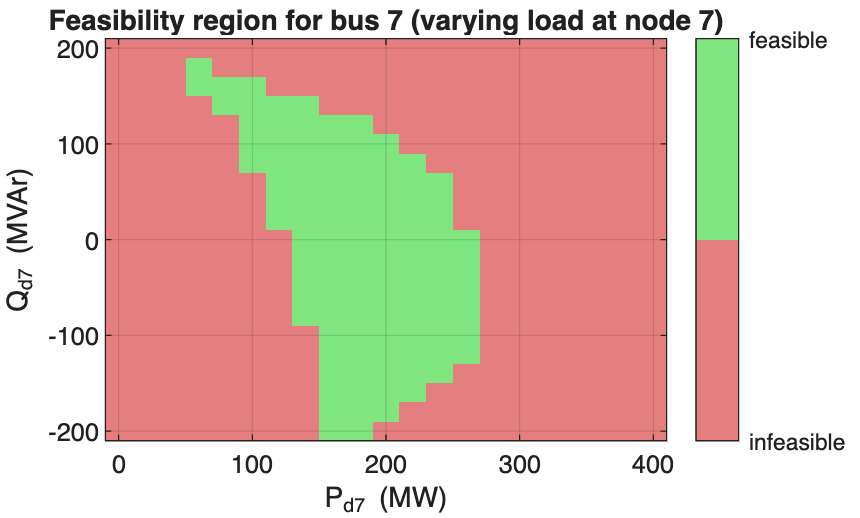


figure; % plot
imagesc(P7_vals, Q7_vals, double(feas));
set(gca,'YDir','normal'); axis tight
colormap([0.9 0.5 0.5; 0.5 0.9 0.5]);
cb = colorbar('Ticks',[0 1],'TickLabels',{'infeasible','feasible'});
xlabel('P_{d7} (MW)'); ylabel('Q_{d7} (MVAr)');
title('Feasibility region for bus 7 (varying load at node 7)'); grid on

% Save the plot as PNG
saveas(gcf, 'feasibility_map_bus7.png');



%% Q7 Security analysis (N-1)
fprintf('Q7: Security analysis (N-1)\n');

Q7: Security analysis (N-1)


cont = [4 5; 4 9; 5 6; 6 7; 7 8; 8 9];
out = pf_security_analysis(nfrom, nto, r, x, b, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, cont, toler, maxiter);
fprintf('\nN-1 contingencies (acceptable range 0.95–1.05 p.u.):\n');


N-1 contingencies (acceptable range 0.95–1.05 p.u.):


for k = 1:numel(out)
    fprintf('Outage %d-%d: Vmin=%.3f, Vmax=%.3f\n', out(k).pair(1), out(k).pair(2), out(k).Vmin, out(k).Vmax);
end

Outage 4-5: Vmin=0.908, Vmax=1.000
Outage 4-9: Vmin=0.794, Vmax=1.000
Outage 5-6: Vmin=0.919, Vmax=1.000
Outage 6-7: Vmin=0.946, Vmax=1.005
Outage 7-8: Vmin=0.933, Vmax=1.000
Outage 8-9: Vmin=0.890, Vmax=1.000
